clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[4.770;8.820;17.257];
u31=[0.652;-0.749;0.117];
r2=[-4.349;8.820;17.257];
u32=[0.652;-0.749;0.117];
r3=[0.515;17.521;17.303];
u33=[-0.652;-0.749;-0.117];
r4=[9.634;17.521;17.303];
u34=[-0.652;-0.749;-0.117];
r5=[1.793;8.582;5.783];
u35=[-0.652;0.749;-0.117];
r6=[10.912;8.582;5.783];
u36=[-0.652;0.749;-0.117];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];

hold on
axis([0 15 0 15]);
for R3=3.5:0.3:13 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     6.5000    3.5000    1.0042


ans =     5.5000    3.8000    1.0071


ans =     5.0000    4.1000    1.0038


ans =     4.6500    4.4000    1.0092


ans =     4.4500    4.7000    1.0036


ans =     4.2500    5.0000    1.0152


ans =     4.1500    5.3000    1.0086


ans =     4.0500    5.6000    1.0104


ans =     4.0000    5.9000    1.0008


ans =     3.9000    6.2000    1.0157


ans =     3.8500    6.5000    1.0155


ans =     3.8000    6.8000    1.0188


ans =     3.8000    7.1000    1.0029


ans =     3.7500    7.4000    1.0112


ans =     3.7000    7.7000    1.0220


ans =     3.7000    8.0000    1.0111


ans =     3.7000    8.3000    1.0013


ans =     3.6500    8.6000    1.0165


ans =     3.6500    8.9000    1.0086


ans =     3.6500    9.2000    1.0015


ans =     3.6000    9.5000    1.0201


ans =     3.6000    9.8000    1.0142


ans =     3.6000   10.1000    1.0088


ans =     3.6000   10.4000    1.0038


ans =     3.5500   10.7000    1.0255


ans =     3.5500   11.0000    1.0213


ans =     3.5500   11.3000    1.0175


ans =     3.5500   11.6000    1.0140


ans =     3.5500   11.9000    1.0107


ans =     3.5500   12.2000    1.0077


ans =     3.5500   12.5000    1.0048


ans =     3.5500   12.8000    1.0022



for R1=6:0.3:13 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     6.0000    3.6000    1.0138


ans =     6.3000    3.5500    1.0023


ans =     6.6000    3.4500    1.0167


ans =     6.9000    3.4000    1.0153


ans =     7.2000    3.3500    1.0178


ans =     7.5000    3.3000    1.0237


ans =     7.8000    3.3000    1.0077


ans =     8.1000    3.2500    1.0185


ans =     8.4000    3.2500    1.0057


ans =     8.7000    3.2000    1.0204


ans =     9.0000    3.2000    1.0101


ans =     9.3000    3.2000    1.0006


ans =     9.6000    3.1500    1.0197


ans =     9.9000    3.1500    1.0119


ans =    10.2000    3.1500    1.0047


ans =    10.5000    3.1000    1.0271


ans =    10.8000    3.1000    1.0211


ans =    11.1000    3.1000    1.0156


ans = 1×3
   11.4000    3.1000    1.0105


ans = 1×3
   11.7000    3.1000    1.0058


ans = 1×3
   12.0000    3.1000    1.0014


ans = 1×3
   12.3000    3.0500    1.0276


ans = 1×3
   12.6000    3.0500    1.0238


ans = 1×3
   12.9000    3.0500    1.0203


 scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')

for R1=2:0.3:9 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans = 1×3
    2.0000    7.2500    1.0003


ans = 1×3
    2.3000    6.9500    1.0046


ans = 1×3
    2.6000    6.7000    1.0007


ans = 1×3
    2.9000    6.4000    1.0102


ans = 1×3
    3.2000    6.1500    1.0102


ans = 1×3
    3.5000    5.9000    1.0115


ans = 1×3
    3.8000    5.7000    1.0018


ans = 1×3
    4.1000    5.4500    1.0034


ans = 1×3
    4.4000    5.2000    1.0043


ans = 1×3
    4.7000    4.9500    1.0036


ans = 1×3
    5.0000    4.7000    1.0010


ans = 1×3
    5.3000    4.4000    1.0068


ans = 1×3
    5.6000    4.1000    1.0096


ans = 1×3
    5.9000    3.8000    1.0095


ans = 1×3
    6.2000    3.5000    1.0068


ans = 1×3
    6.5000    3.2000    1.0019


ans = 1×3
    6.8000    2.8500    1.0050


ans = 1×3
    7.1000    2.5000    1.0069


ans = 1×3
    7.4000    2.1500    1.0082


ans = 1×3
    7.7000    1.8500    1.0001


ans = 1×3
    8.0000    1.5000    1.0016


ans = 1×3
    8.3000    1.1500    1.0037


ans = 1×3
    8.6000    0.8000    1.0064


ans = 1×3
    8.9000    0.5000    1.0001



 scatter(x2,y2,10,'markerfacecolor',[29, 50, 67]/256,...
        'markeredgecolor',[29, 50, 67]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','13')


for R1=2:0.3:9.6 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    2.0000    7.6500    1.0017


ans = 1×3
    2.3000    7.3500    1.0023


ans = 1×3
    2.6000    7.0500    1.0052


ans = 1×3
    2.9000    6.7500    1.0102


ans = 1×3
    3.2000    6.5000    1.0061


ans = 1×3
    3.5000    6.2500    1.0033


ans = 1×3
    3.8000    6.0000    1.0015


ans = 1×3
    4.1000    5.7500    1.0001


ans = 1×3
    4.4000    5.4500    1.0095


ans = 1×3
    4.7000    5.2000    1.0074


ans = 1×3
    5.0000    4.9500    1.0043


ans = 1×3
    5.3000    4.6500    1.0103


ans = 1×3
    5.6000    4.4000    1.0039


ans = 1×3
    5.9000    4.1000    1.0060


ans = 1×3
    6.2000    3.8000    1.0060


ans = 1×3
    6.5000    3.5000    1.0044


ans = 1×3
    6.8000    3.2000    1.0013


ans = 1×3
    7.1000    2.8500    1.0067


ans = 1×3
    7.4000    2.5500    1.0019


ans = 1×3
    7.7000    2.2000    1.0062


ans = 1×3
    8.0000    1.9000    1.0009


ans = 1×3
    8.3000    1.5500    1.0053


ans = 1×3
    8.6000    1.2500    1.0003


ans = 1×3
    8.9000    0.9000    1.0052


ans = 1×3
    9.2000    0.6000    1.0009


ans = 1×3
    9.5000    0.2500    1.0066



 scatter(x3,y3,10,'markerfacecolor',[84, 130, 53]/256,...
        'markeredgecolor',[84, 130, 53]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','14')

for R3=2:0.3:13 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
    9.0500    2.0000    1.0011


ans = 1×3
    7.7500    2.3000    1.0002


ans = 1×3
    7.1000    2.6000    1.0057


ans = 1×3
    6.7500    2.9000    1.0049


ans = 1×3
    6.5000    3.2000    1.0101


ans = 1×3
    6.3500    3.5000    1.0085


ans = 1×3
    6.2500    3.8000    1.0049


ans = 1×3
    6.1500    4.1000    1.0088


ans = 1×3
    6.1000    4.4000    1.0042


ans = 1×3
    6.0500    4.7000    1.0034


ans = 1×3
    6.0000    5.0000    1.0057


ans = 1×3
    5.9500    5.3000    1.0104


ans = 1×3
    5.9500    5.6000    1.0014


ans = 1×3
    5.9000    5.9000    1.0096


ans = 1×3
    5.9000    6.2000    1.0030


ans = 1×3
    5.8500    6.5000    1.0135


ans = 1×3
    5.8500    6.8000    1.0086


ans = 1×3
    5.8500    7.1000    1.0043


ans = 1×3
    5.8500    7.4000    1.0005


ans = 1×3
    5.8000    7.7000    1.0137


ans = 1×3
    5.8000    8.0000    1.0107


ans = 1×3
    5.8000    8.3000    1.0080


ans = 1×3
    5.8000    8.6000    1.0056


ans = 1×3
    5.8000    8.9000    1.0035


ans = 1×3
    5.8000    9.2000    1.0015


ans = 1×3
    5.7500    9.5000    1.0167


ans = 1×3
    5.7500    9.8000    1.0151


ans = 1×3
    5.7500   10.1000    1.0136


ans = 1×3
    5.7500   10.4000    1.0123


ans = 1×3
    5.7500   10.7000    1.0111


ans = 1×3
    5.7500   11.0000    1.0099


ans = 1×3
    5.7500   11.3000    1.0089


ans = 1×3
    5.7500   11.6000    1.0079


ans = 1×3
    5.7500   11.9000    1.0070


ans = 1×3
    5.7500   12.2000    1.0062


ans = 1×3
    5.7500   12.5000    1.0054


ans = 1×3
    5.7500   12.8000    1.0047



 scatter(x4,y4,10,'markerfacecolor',[63, 125, 162]/256,...
        'markeredgecolor',[63, 125, 162]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','15')

for R3=2:0.3:13 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];   
end

ans = 1×3
    9.0000    2.0000    1.0013


ans = 1×3
    8.0500    2.3000    1.0034


ans = 1×3
    7.5500    2.6000    1.0059


ans = 1×3
    7.2500    2.9000    1.0072


ans = 1×3
    7.0500    3.2000    1.0086


ans = 1×3
    6.9000    3.5000    1.0119


ans = 1×3
    6.8000    3.8000    1.0121


ans = 1×3
    6.7500    4.1000    1.0054


ans = 1×3
    6.7000    4.4000    1.0028


ans = 1×3
    6.6500    4.7000    1.0035


ans = 1×3
    6.6000    5.0000    1.0068


ans = 1×3
    6.5500    5.3000    1.0121


ans = 1×3
    6.5500    5.6000    1.0046


ans = 1×3
    6.5000    5.9000    1.0128


ans = 1×3
    6.5000    6.2000    1.0073


ans = 1×3
    6.5000    6.5000    1.0026


ans = 1×3
    6.4500    6.8000    1.0133


ans = 1×3
    6.4500    7.1000    1.0097


ans = 1×3
    6.4500    7.4000    1.0065


ans = 1×3
    6.4500    7.7000    1.0037


ans = 1×3
    6.4500    8.0000    1.0012


ans = 1×3
    6.4000    8.3000    1.0142


ans = 1×3
    6.4000    8.6000    1.0122


ans = 1×3
    6.4000    8.9000    1.0104


ans = 1×3
    6.4000    9.2000    1.0087


ans = 1×3
    6.4000    9.5000    1.0072


ans = 1×3
    6.4000    9.8000    1.0059


ans = 1×3
    6.4000   10.1000    1.0047


ans = 1×3
    6.4000   10.4000    1.0035


ans = 1×3
    6.4000   10.7000    1.0025


ans = 1×3
    6.4000   11.0000    1.0016


ans = 1×3
    6.4000   11.3000    1.0007


ans = 1×3
    6.3500   11.6000    1.0155


ans = 1×3
    6.3500   11.9000    1.0147


ans = 1×3
    6.3500   12.2000    1.0140


ans = 1×3
    6.3500   12.5000    1.0134


ans = 1×3
    6.3500   12.8000    1.0128


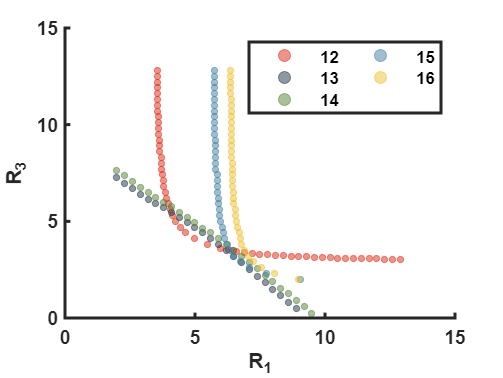


 scatter(x5,y5,10,'markerfacecolor',[239, 193, 48]/256,...
        'markeredgecolor',[239, 193, 48]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','16')



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
